# Figure 3I

**Load Data**

clear
[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = '..\..\FINAL DATA files';

load([dataDir filesep 'C001_data.mat'],'S','settings','allIF');

% S = loadData(conditions, dataDir);
conditions = settings.conditions

conditions = 15×5 cell array
    {'siFOXM1 CDK1i'  }    {[2 3]}    {[  2 3]}    {[1]}    {[0]}
    {'siFOXM1 CDK2i'  }    {[4 5]}    {[  2 3]}    {[1]}    {[0]}
    {'siFOXM1 DMSO'   }    {[6 7]}    {[  2 3]}    {[1]}    {[0]}
    {'siE2F1-3 CDK1i' }    {[2 3]}    {[  4 5]}    {[1]}    {[0]}
    {'siE2F1-3 CDK2i' }    {[4 5]}    {[  4 5]}    {[1]}    {[0]}
    {'siE2F1-3 DMSO'  }    {[6 7]}    {[  4 5]}    {[1]}    {[0]}
    {'siE2F7 CDK1i'   }    {[2 3]}    {[  6 7]}    {[1]}    {[0]}
    {'siE2F7 CDK2i'   }    {[4 5]}    {[  6 7]}    {[1]}    {[0]}
    {'siE2F7 DMSO'    }    {[6 7]}    {[  6 7]}    {[1]}    {[0]}
    {'siFBXW7 CDK1i'  }    {[2 3]}    {[  8 9]}    {[1]}    {[0]}
    {'siFBXW7 CDK2i'  }    {[4 5]}    {[  8 9]}    {[1]}    {[0]}
    {'siFBXW7 DMSO'   }    {[6 7]}    {[  8 9]}    {[1]}    {[0]}
    {'siControl CDK1i'}    {[2 3]}    {[10 11]}    {[1]}    {[0]}
    {'siControl CDK2i'}    {[4 5]}    {[10 11]}    {[1]}    {[0]}
    {'siControl DMSO' }    {[6 7]}    {[10 11]}

framesPerHr = 60/12;
 frameDrugAdded = 0;
frameEdU = 0;
timeStart = 0;

folding =5;

numFrames = size(S(1).area,2);
xFrames = 1:numFrames;
xTime = (xFrames-1)./framesPerHr;

times = arrayfun(@(x)(numFrames - x.POI)/framesPerHr,S,'UniformOutput',false);
[S.POI_time] = times{:};

for i = 1:length(S)
    S(i).frameDrugAdded = conditions{i,5};
    S(i).POI_realtime = S(i).POI/framesPerHr;
    S(i).POI_drug_time = ( S(i).frameDrugAdded - S(i).POI)/framesPerHr;
    S(i).drug_time = S(i).frameDrugAdded/framesPerHr;
end
drug_time = frameDrugAdded/framesPerHr;

**Gate cells**

for i = 1:length(S)
    dat = S(i);
   
    
    cdkHighGate = false(length(dat.POI(:,1)),1);
    cdkLowGate = false(length(dat.POI(:,1)),1);
     cdkGateAll = false(length(dat.POI(:,1)),1);
crlGate = false(length(dat.POI(:,1)),1);

    for n = 1:length(dat.POI(:,1))
      
        if dat.POI(n,1) + round(6*framesPerHr) <= numFrames 
            cdkHighGate(n) = dat.cdk(n,dat.POI(n,1) + round(6*framesPerHr)) > .7;
        end
        if dat.POI(n,1) + round(6*framesPerHr) <= numFrames 

            cdkLowGate(n) = dat.cdk(n,dat.POI(n,1) + round(6*framesPerHr)) < .7;
            cdkGateAll(n) = ~isnan(dat.cdk(n,dat.POI(n,1) + round(6*framesPerHr)));
        end
        if dat.POI(n,1) > 1 * framesPerHr
            crlGate(n) = dat.crlNuc(n,dat.POI(n,1) - 1 * framesPerHr) >  100;
        end

    end
  
       S(i).cdkGateAll = cdkGateAll;
%     S(i).cdkGate = cdkGate;
   S(i).crlGate = crlGate;
        S(i).cdkHighGate = cdkHighGate;
         S(i).cdkLowGate = cdkLowGate;

end

3I left

conds=[15 14];
timeGate = [0 1];
colors = [.5 .5 .5; .1 .4 1; .6 .9 .2;.9 .4 0;1 .6 0; 1 .3 .2; 1 .647 .671; .855 .384 .49; .647 .22 .376; .271 .035 .125; .525 .075 .788; .075 .322 .702];
figure('unit','inches','position',[0 0 4 4])
hold on
axis square;
POI_align = 3;
for i=1:length(conds)
    c = conds(i);
    data = S(c);
   
    inds = ~isnan(S(conds(i)).POI(:,POI_align)) &  ...
         S(conds(i)).POI_realtime(:,1) <= timeGate(2) & S(conds(i)).POI_realtime(:,1) >= timeGate(1) & S(conds(i)).goodCdk;
sum(inds)
    ydata = data.cdk(inds,:);
    POI = data.POI(inds,POI_align) ;
    
    [frames, medSig, semCRL] =get_mean_trace(ydata,POI,1);
    shadedErrorBar((frames)/framesPerHr,medSig,2*semCRL,'lineProps',{'Color',colors(i,:),'LineWidth',1.5});
end

ans = 110

ans = 119

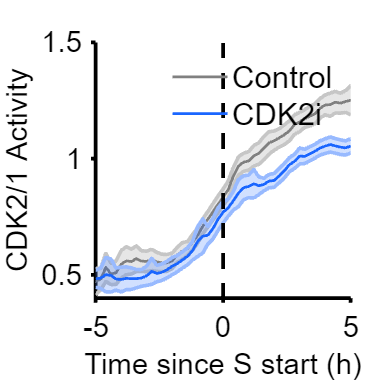


ylabel({'CDK2/1 Activity'});
xlabel('Time since S start (h)');
legend('Control','CDK2i','box','off','Location','northeast','fontsize',17);

xlim([-5 5]); 
ylim([.4 1.5]);
% yticks(20:50:120)
vline([0],'k--')

 % print_pdf(['fig_3Ileft.pdf'])

3I right

conds=[15 14];
timeGate = [0 1];
colors = [.5 .5 .5; .1 .4 1; .6 .9 .2;.9 .4 0;1 .6 0; 1 .3 .2; 1 .647 .671; .855 .384 .49; .647 .22 .376; .271 .035 .125; .525 .075 .788; .075 .322 .702];
figure('unit','inches','position',[0 0 4 4])
hold on
axis square;
POI_align = 3;
for i=1:length(conds)
    c = conds(i);
    data = S(c);
   
    inds = ~isnan(S(conds(i)).POI(:,POI_align)) &  ...
         S(conds(i)).POI_realtime(:,1) <= timeGate(2) & S(conds(i)).POI_realtime(:,1) >= timeGate(1);
sum(inds)
    ydata = data.sigNuc(inds,:);
    POI = data.POI(inds,POI_align) ;
    
    [frames, medSig, semCRL] =get_mean_trace(ydata,POI,1);
    shadedErrorBar((frames)/framesPerHr,medSig,2*semCRL,'lineProps',{'Color',colors(i,:),'LineWidth',1.5});
end

ans = 110

ans = 119

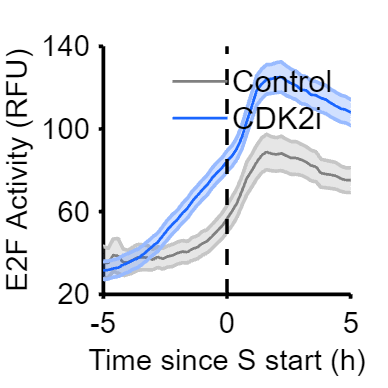


ylabel({'E2F Activity (RFU)'});
xlabel('Time since S start (h)');
legend('Control','CDK2i','box','off','Location','northeast','fontsize',17);

xlim([-5 5]); 
ylim([20 140]);
yticks(20:40:140)
vline([0],'k--')

 % print_pdf(['fig_3iright.pdf'])